clc; clearvars; close all;

project_root = './';

addpath(fullfile(project_root, 'dynamics_library'));
addpath(fullfile(project_root, 'data'));

disp('✅ Paths added.');

✅ Paths added.



%% 1) Load numeric dynamics + COM
% NOTE: COM_sub is stored in mm_dynamics_numeric.mat for your project.
data_file = fullfile(project_root, 'data', 'mm_dynamics_numeric.mat');
load(data_file, ...
    'q', 'q_sym', ...        % q(t) and algebraic q
    'COM_sub', ...           % COM with parameters substituted
    'phys');

% q is  [x_m(t); y_m(t); theta_m(t); theta_r(t); theta_l(t); theta_1(t); theta_2(t); theta_3(t)]
% q_sym is [x_m;    y_m;    theta_m;    theta_r;    theta_l;    theta_1;    theta_2;    theta_3]

disp('✅ Dynamics + COM_sub loaded.');

✅ Dynamics + COM_sub loaded.



%% 2) Build algebraic expressions for end-effector position p_e(q)
% Use COM of link 3 as end-effector point.
x_e = COM_sub.manip.x_cm_3;
y_e = COM_sub.manip.y_cm_3;
z_e = COM_sub.manip.z_cm_3;

% q(t) entries:
q_t = q;          % q_t(1)=x_m(t), ..., q_t(8)=theta_3(t)
% algebraic q entries:
q_alg = q_sym;    % q_alg(1)=x_m, ..., q_alg(8)=theta_3

% Substitute q(t) -> q_sym element-wise for robustness:
p_e = [x_e; y_e; z_e];
for k = 1:numel(q_t)
    p_e = subs(p_e, q_t(k), q_alg(k));
end
p_e = simplify(p_e, 'Steps', 40);

disp('✅ End-effector position p_e(q) expressed in algebraic variables.');

✅ End-effector position p_e(q) expressed in algebraic variables.



%% 3) Manipulator Jacobian J_arm for joints (theta_1, theta_2, theta_3)
% q_sym = [x_m; y_m; theta_m; theta_r; theta_l; theta_1; theta_2; theta_3]
x_m     = q_sym(1);
y_m     = q_sym(2);
theta_m = q_sym(3);
theta_r = q_sym(4);
theta_l = q_sym(5);
theta_1 = q_sym(6);
theta_2 = q_sym(7);
theta_3 = q_sym(8);

q_arm = [theta_1; theta_2; theta_3];

J_arm = jacobian(p_e, q_arm);   % 3x3 Jacobian (linear velocity)
J_arm = simplify(J_arm, 'Steps', 40);

disp('✅ 3x3 manipulator Jacobian J_arm(q) computed.');

✅ 3x3 manipulator Jacobian J_arm(q) computed.



%% 4) Remove base influence (pure arm analysis)
% Freeze base pose and wheel angles: x_m = y_m = theta_m = theta_r = theta_l = 0
J_arm_base0 = subs(J_arm, [x_m, y_m, theta_m, theta_r, theta_l], [0, 0, 0, 0, 0]);
J_arm_base0 = simplify(J_arm_base0, 'Steps', 40);

disp('✅ J_arm(q_arm) with base pose fixed computed.');

✅ J_arm(q_arm) with base pose fixed computed.



%% 5) Symbolic singularity condition: det(J) = 0
detJ = simplify(det(J_arm_base0), 'Steps', 40);
detJ_factored = factor(detJ);

disp('Symbolic det(J_arm) (simplified):');

Symbolic det(J_arm) (simplified):


disp(detJ);

$$0.0068\,\sin\left(\theta_{2}\right)-0.0090\,\sin\left(\theta_{3}\right)-0.0135\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-0.0068\,{\cos\left(\theta_{3}\right)}^{2}\,\sin\left(\theta_{2}\right)-0.0068\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{3}\right)$$

disp('Factored det(J_arm):');

Factored det(J_arm):


disp(detJ_factored);

$$\left(\begin{array}{cc} -0.0022 & 4\,\sin\left(\theta_{3}\right)-3\,\sin\left(\theta_{2}\right)+6\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+3\,{\cos\left(\theta_{3}\right)}^{2}\,\sin\left(\theta_{2}\right)+3\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{3}\right) \end{array}\right)$$


%% 6) Numerical singularity scan over theta2, theta3
% We fix theta1 = 0 (since it does not change singularity locations).
theta1_fixed = 0;

% Dense grid for better resolution
ep = 0.5;
theta2_vals = linspace(-pi - ep, pi + ep, 61);   % 61 points
theta3_vals = linspace(-pi - ep, pi + ep, 61);   % 61 points

[TH2, TH3] = meshgrid(theta2_vals, theta3_vals);
det_vals = zeros(size(TH2));
rank_vals = zeros(size(TH2));

tol_rank = 1e-8;
tol_det  = 1e-4;   % tolerance for considering detJ "numerically zero"

for i = 1:numel(TH2)
    th2 = TH2(i);
    th3 = TH3(i);
    
    % Evaluate Jacobian at (theta1_fixed, th2, th3)
    J_num = double(subs(J_arm_base0, ...
        [theta_1, theta_2, theta_3], ...
        [theta1_fixed, th2, th3]));
    
    det_vals(i)  = det(J_num);
    rank_vals(i) = rank(J_num, tol_rank);
end

% Identify singular configurations (rank < 3 or |det| small)
is_singular = (rank_vals < 3) | (abs(det_vals) < tol_det);

% Print a few unique singular (theta2, theta3) pairs
[rows, cols] = find(is_singular);
sing_list = unique([TH2(is_singular), TH3(is_singular)], 'rows');

fprintf('\n=== Arm singular configurations (theta1 = %.2f) ===\n', theta1_fixed);


=== Arm singular configurations (theta1 = 0.00) ===


fprintf('Showing first 10 (theta2, theta3) pairs (rad):\n');

Showing first 10 (theta2, theta3) pairs (rad):


for k = 1:min(10, size(sing_list,1))
    fprintf('theta2 = %+ .3f, theta3 = %+ .3f\n', sing_list(k,1), sing_list(k,2));
end

theta2 = -3.642, theta3 = -3.156
theta2 = -3.642, theta3 = +0.000
theta2 = -3.642, theta3 = +3.156
theta2 = -3.520, theta3 = -3.156
theta2 = -3.520, theta3 = +0.000
theta2 = -3.520, theta3 = +3.156
theta2 = -3.399, theta3 = -3.156
theta2 = -3.399, theta3 = -1.942
theta2 = -3.399, theta3 = +0.000
theta2 = -3.399, theta3 = +3.156


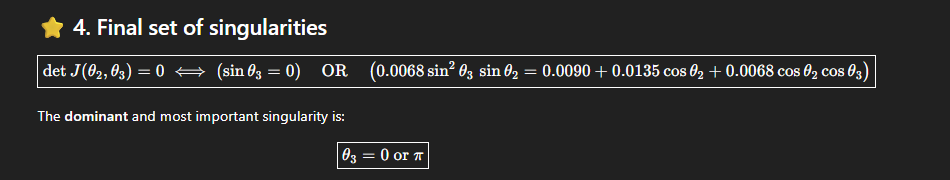

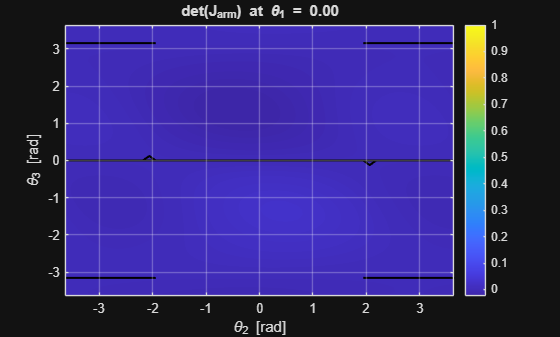

% Optional: visualize det(J) heatmap
figure;
contourf(TH2, TH3, det_vals, 40, 'LineStyle', 'none');
colorbar;
hold on;
contour(TH2, TH3, is_singular, [1 1], 'k', 'LineWidth', 1.5); % det~0 curve
xlabel('\theta_2 [rad]');
ylabel('\theta_3 [rad]');
title(sprintf('det(J_{arm}) at \\theta_1 = %.2f', theta1_fixed));
grid on;


%% 7) Base kinematic singularity via R(q)
has_R_fun = exist('mm_R_fun', 'file') == 2;

if has_R_fun
    fprintf('\n=== Base R(q) rank checks ===\n');
    theta_m_vals = linspace(-pi, pi, 9);
    for thm = theta_m_vals
        q_base = zeros(8,1);
        q_base(3) = thm;   % theta_m
        R_num = mm_R_fun(q_base);
        rR = rank(R_num, 1e-8);
        fprintf('theta_m = %+ .2f -> rank(R) = %d\n', thm, rR);
    end
else
    disp('⚠️ mm_R_fun not found on path; base kinematic singularity check skipped.');
end


=== Base R(q) rank checks ===


theta_m = -3.14 -> rank(R) = 5
theta_m = -2.36 -> rank(R) = 5
theta_m = -1.57 -> rank(R) = 5
theta_m = -0.79 -> rank(R) = 5
theta_m = +0.00 -> rank(R) = 5
theta_m = +0.79 -> rank(R) = 5
theta_m = +1.57 -> rank(R) = 5
theta_m = +2.36 -> rank(R) = 5
theta_m = +3.14 -> rank(R) = 5



disp('✅ Kinematic singularity analysis script finished.');

✅ Kinematic singularity analysis script finished.
